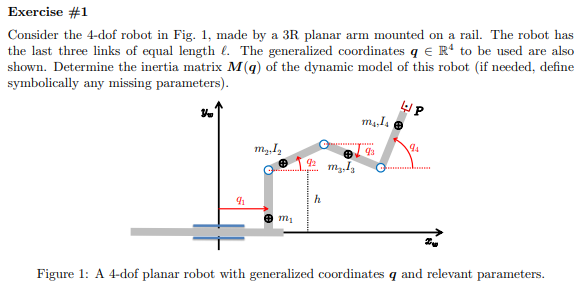

% % % This part is isolated from previous section
% % clear;clc
% %
% % % syms k q1(t) q2(t) q3(t)
% sigma = [1,0,0,0];
% n = length(sigma);
% % t = sym('t', 'real');
% q = sym('q_', [n 1],'real');
% qd = sym('q_dot_', [n 1],'real');
% qdd = sym('q_ddot_', [n 1],'real');
% %
% dc = sym('dc_', [n 1],'real');
% % k = sym('k', [n 1],'real');
% l = sym('l_', [n 1],'real');
% m = sym('m_', [n 1],'real');
% I = sym('I_', [n 1],'real');
% alpha_angle=sym('alpha','real')
% g0 = sym('g0','real');
% g=[g0,0,0]';

defining z struct

% R2Robot=['prrr';'xxxx';sigma]
% z = Gen_param(n);
% z.sigmaD=R2Robot;
% z.l=l;
% z.q=q;
% z.q_dot=qd;
% z.dc=dc;
% z.m=m;
% z.I=I;
% z.methodD=1;
% % z.dhTable=[]
% z.firstParam='alpha';
% % z.rc=[];
% % z.movingframes=[];
% z.angle_=sym(zeros(1,n));
% l_0=sym('l','real');
% z.opt_expr={l,[l_0,l_0,l_0,l_0]'};%not necessary
% 
% % z.rcdefined=true;

## axis offset

% 
% h=sym('h','real')
% %x,y,z
% z.xyx_offset=sym(zeros(3,n));
% z.xyx_offset(:,1)=[0,h,0]';%

% %Global q reference?
% % clear
% % z.q_global
% z.global_q_reference=true;
% if(z.global_q_reference)
%     [z.q_global,z.q_dot_global]=convert_local2global_q(z.q,z.q_dot,z.sigmaD);
% end

% 
% %
% %
% % xyonly=true
% % [f,J,V,J_ps,PCVar,PC_EEShort,VarShortRobot]= getGenericPC_EE2(R2Robot,l,q,qd,dc,m,I,xyonly)
% % VarShortRobot.M
% % angle_desired=[0,0]
% % l(1)=0
% [Pc,vc,w,T,Ti,M,VarShortRobot,Trans] = getGenericPC2(z);

% M
% Pc
% simplify((Ti'))
% vc
% simplify(Trans.PTotal)
% Trans.PPartial{:}


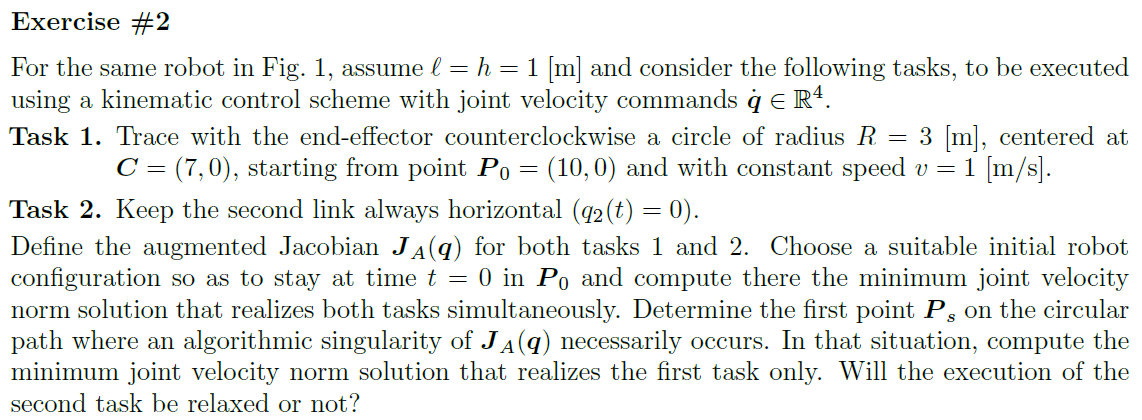

% This part is isolated from previous section
clear;clc

% syms k q1(t) q2(t) q3(t)
sigma = [1,0,0,0];
n = length(sigma);
% t = sym('t', 'real');
q = sym('q_', [n 1],'real');
qd = sym('q_dot_', [n 1],'real');
qdd = sym('q_ddot_', [n 1],'real');
%
dc = sym('dc_', [n 1],'real');
% k = sym('k', [n 1],'real');
l = sym('l_', [n 1],'real');
m = sym('m_', [n 1],'real');
I = sym('I_', [n 1],'real');
alpha_angle=sym('alpha','real')

$$alpha\_angle = \alpha$$

g0 = sym('g0','real');
g=[g0,0,0]';

defining z struct

R2Robot=['prrr';'xxxx';sigma]

R2Robot = 3×4 char array
    'prrr'
    'xxxx'
    '   '


z = Gen_param(n);
z.sigmaD=R2Robot;
z.l=l;
z.q=q;
z.q_dot=qd;
z.dc=dc;
z.m=m;
z.I=I;
z.methodD=1;
% z.dhTable=[]
z.firstParam='alpha';
% z.rc=[];
% z.movingframes=[];
z.angle_=sym(zeros(1,n));
% l_0=sym("l","real");
l_0=1%sym('l','real')

l_0 = 1

h=sym('h','real');
h_=1;
z.opt_expr={[l;h],[l_0,l_0,l_0,l_0,h_]'};%not necessary

% z.rcdefined=true;

## axis offset



%x,y,z
z.xyx_offset=sym(zeros(3,n));
z.xyx_offset(:,1)=[0,h,0]';%

%Global q reference?
% clear
% z.q_global
z.global_q_reference=true;
if(z.global_q_reference)
    [z.q_global,z.q_dot_global]=convert_local2global_q(z.q,z.q_dot,z.sigmaD);
end

Defining task order

pd={sym('pd_1_',[1,1],'real'),sym('pd_2_',[2,1],'real')};
% z.task_defined={struct('f','end_effector','pd_',pd{2},'pd_dot_',[0.1,-0.5]'),struct('f',sum([q(1),q(2),0]),'pd_',pd{1},'pd_dot_',[0])} %pc is note necessary
z.task_defined={struct('f','end_effector','pd_',pd{2}),struct('f',q(2),'pd_',pd{1})} ;%pc is note necessary
%
z.task_defined

ans = 1×2 cell array
    {1×1 struct}    {1×1 struct}


% xyonly=true
[f,J,V,J_ps,PCVar,PC_EEShort,VarShortRobot,PC_EE]= getGenericPC_EE2(z);

rcdefined = logical
   1


z = struct with fields:
                  sigmaD: [3×4 char]
                       l: [4×1 sym]
                      l_: []
                       q: [4×1 sym]
                   q_dot: [4×1 sym]
                      q_: []
                  q_dot_: []
                      dc: [4×1 sym]
                       m: [4×1 sym]
                       I: [4×1 sym]
                 methodD: 1
                 dhTable: []
              firstParam: 'alpha'
                       t: [1×1 sym]
                      rc: []
            movingframes: 0
                       n: 4
                  angle_: [1×4 sym]
               rcdefined: 1
                opt_expr: {[5×1 sym]  [5×1 double]}
                collides: []
                joint_on: 1
                  xyonly: 0
    prismatic_CoM_method: [1 1 1 1]
               dc_method: 0
                     g_q: []
                 isMotor: 0
                       g: []
            task_defined: {[1×1 struct]  [1×1 struct]}
              xyx_

si falla aquí está el error


anglerot = 1×1 cell array
    {4×4 sym}


$$a = l_{2}$$

d = 0

$$a = l_{3}$$

d = 0

$$a = l_{4}$$

d = 0

    "PAY!!!!!!!!!!! attention!!!!! offset in axis is different of zero"

    "PAY!!!!!!!!!!! attention!!!!! offset in axis is different of zero"

    "PAY!!!!!!!!!!! attention!!!!! offset in axis is different of zero"

    "PAY!!!!!!!!!!! attention!!!!! offset in axis is different of zero"

method with PC , pay attention!
moving frames OFF!!


$$Ti = \frac{m_{1}\,{{\dot{q}}_{1}}^{2}}{2}$$

moving frames OFF!!


$$Ti = \left(\begin{array}{cc} \frac{m_{1}\,{{\dot{q}}_{1}}^{2}}{2} & \frac{I_{2}\,{{\dot{q}}_{2}}^{2}}{2}+\frac{m_{2}\,\left({{\mathrm{dc}}_{2}}^{2}\,{{\dot{q}}_{2}}^{2}-2\,\sin\left(q_{2}\right)\,{\mathrm{dc}}_{2}\,{\dot{q}}_{1}\,{\dot{q}}_{2}+{{\dot{q}}_{1}}^{2}\right)}{2} \end{array}\right)$$

moving frames OFF!!


$$Ti = \left(\begin{array}{ccc} \frac{m_{1}\,{{\dot{q}}_{1}}^{2}}{2} & \frac{I_{2}\,{{\dot{q}}_{2}}^{2}}{2}+\frac{m_{2}\,\left({{\mathrm{dc}}_{2}}^{2}\,{{\dot{q}}_{2}}^{2}-2\,\sin\left(q_{2}\right)\,{\mathrm{dc}}_{2}\,{\dot{q}}_{1}\,{\dot{q}}_{2}+{{\dot{q}}_{1}}^{2}\right)}{2} & \frac{m_{3}\,\left({{\dot{q}}_{1}}^{2}+\left(-2\,\sin\left(q_{2}\right)\right)\,{\dot{q}}_{1}\,{\dot{q}}_{2}+\left(-2\,{\mathrm{dc}}_{3}\,\sin\left(q_{3}\right)\right)\,{\dot{q}}_{1}\,{\dot{q}}_{3}+{{\dot{q}}_{2}}^{2}+\left(2\,{\mathrm{dc}}_{3}\,\cos\left(q_{2}-q_{3}\right)\right)\,{\dot{q}}_{2}\,{\dot{q}}_{3}+{{\mathrm{dc}}_{3}}^{2}\,{{\dot{q}}_{3}}^{2}\right)}{2}+\frac{I_{3}\,{{\dot{q}}_{3}}^{2}}{2} \end{array}\right)$$

moving frames OFF!!


$$Ti = \left(\begin{array}{cccc} \frac{m_{1}\,{{\dot{q}}_{1}}^{2}}{2} & \frac{I_{2}\,{{\dot{q}}_{2}}^{2}}{2}+\frac{m_{2}\,\left({{\mathrm{dc}}_{2}}^{2}\,{{\dot{q}}_{2}}^{2}-2\,\sin\left(q_{2}\right)\,{\mathrm{dc}}_{2}\,{\dot{q}}_{1}\,{\dot{q}}_{2}+{{\dot{q}}_{1}}^{2}\right)}{2} & \frac{m_{3}\,\left({{\dot{q}}_{1}}^{2}+\left(-2\,\sin\left(q_{2}\right)\right)\,{\dot{q}}_{1}\,{\dot{q}}_{2}+\left(-2\,{\mathrm{dc}}_{3}\,\sin\left(q_{3}\right)\right)\,{\dot{q}}_{1}\,{\dot{q}}_{3}+{{\dot{q}}_{2}}^{2}+\left(2\,{\mathrm{dc}}_{3}\,\cos\left(q_{2}-q_{3}\right)\right)\,{\dot{q}}_{2}\,{\dot{q}}_{3}+{{\mathrm{dc}}_{3}}^{2}\,{{\dot{q}}_{3}}^{2}\right)}{2}+\frac{I_{3}\,{{\dot{q}}_{3}}^{2}}{2} & \frac{m_{4}\,{{\mathrm{dc}}_{4}}^{2}\,{{\dot{q}}_{4}}^{2}}{2}-m_{4}\,\sin\left(q_{4}\right)\,{\mathrm{dc}}_{4}\,{\dot{q}}_{1}\,{\dot{q}}_{4}+m_{4}\,\cos\left(q_{2}-q_{4}\right)\,{\mathrm{dc}}_{4}\,{\dot{q}}_{2}\,{\dot{q}}_{4}+m_{4}\,\cos\left(q_{3}-q_{4}\right)\,{\mathrm{dc}}_{4}\,{\dot{q}}_{3}\,{\dot{q}}_{4}+\frac{m_{4}\,{{\dot{q}}_{1}}^{2}}{2}-m_{4}\,\sin\left(q_{2}\right)\,{\dot{q}}_{1}\,{\dot{q}}_{2}-m_{4}\,\sin\left(q_{3}\right)\,{\dot{q}}_{1}\,{\dot{q}}_{3}+\frac{m_{4}\,{{\dot{q}}_{2}}^{2}}{2}+m_{4}\,\cos\left(q_{2}-q_{3}\right)\,{\dot{q}}_{2}\,{\dot{q}}_{3}+\frac{m_{4}\,{{\dot{q}}_{3}}^{2}}{2}+\frac{I_{4}\,{{\dot{q}}_{4}}^{2}}{2} \end{array}\right)$$

$$To\_derive = \left(\begin{array}{cccc} 1 & -\sin\left(q_{2}\left(t\right)\right) & -\sin\left(q_{3}\left(t\right)\right) & -\sin\left(q_{4}\left(t\right)\right)\\ 0 & \cos\left(q_{2}\left(t\right)\right) & \cos\left(q_{3}\left(t\right)\right) & \cos\left(q_{4}\left(t\right)\right)\\ 0 & 0 & 0 & 0 \end{array}\right)$$

$$q\_t = \left(\begin{array}{c} q_{1}\left(t\right)\\ q_{2}\left(t\right)\\ q_{3}\left(t\right)\\ q_{4}\left(t\right) \end{array}\right)$$

z_derivated = struct with fields:
    dot_t: [3×4 sym]


z_derivated = struct with fields:
     dot_t: [3×4 sym]
    ddot_t: [3×4 sym]


z_derivated = struct with fields:
     dot_t: [3×4 sym]
    ddot_t: [3×4 sym]
    tdot_t: [3×4 sym]


z_derivated = struct with fields:
        dot_t: [3×4 sym]
       ddot_t: [3×4 sym]
       tdot_t: [3×4 sym]
          dot: [3×4 sym]
    dot_short: []


$$new\_dep\_var = \left(\begin{array}{cccc} q_{1} & {\dot{q}}_{1} & {\ddot{q}}_{1} & {\dddot{q}}_{1}\\ q_{2} & {\dot{q}}_{2} & {\ddot{q}}_{2} & {\dddot{q}}_{2}\\ q_{3} & {\dot{q}}_{3} & {\ddot{q}}_{3} & {\dddot{q}}_{3}\\ q_{4} & {\dot{q}}_{4} & {\ddot{q}}_{4} & {\dddot{q}}_{4} \end{array}\right)$$

z_derivated = struct with fields:
        dot_t: [3×4 sym]
       ddot_t: [3×4 sym]
       tdot_t: [3×4 sym]
          dot: [3×4 sym]
    dot_short: []


z_derivated = struct with fields:
         dot_t: [3×4 sym]
        ddot_t: [3×4 sym]
        tdot_t: [3×4 sym]
           dot: [3×4 sym]
     dot_short: []
          ddot: [3×4 sym]
    ddot_short: []


$$new\_dep\_var = \left(\begin{array}{cccc} q_{1} & {\dot{q}}_{1} & {\ddot{q}}_{1} & {\dddot{q}}_{1}\\ q_{2} & {\dot{q}}_{2} & {\ddot{q}}_{2} & {\dddot{q}}_{2}\\ q_{3} & {\dot{q}}_{3} & {\ddot{q}}_{3} & {\dddot{q}}_{3}\\ q_{4} & {\dot{q}}_{4} & {\ddot{q}}_{4} & {\dddot{q}}_{4} \end{array}\right)$$

z_derivated = struct with fields:
         dot_t: [3×4 sym]
        ddot_t: [3×4 sym]
        tdot_t: [3×4 sym]
           dot: [3×4 sym]
     dot_short: []
          ddot: [3×4 sym]
    ddot_short: []


z_derivated = struct with fields:
         dot_t: [3×4 sym]
        ddot_t: [3×4 sym]
        tdot_t: [3×4 sym]
           dot: [3×4 sym]
     dot_short: []
          ddot: [3×4 sym]
    ddot_short: []
          tdot: [3×4 sym]
    tdot_short: []


$$new\_dep\_var = \left(\begin{array}{cccc} q_{1} & {\dot{q}}_{1} & {\ddot{q}}_{1} & {\dddot{q}}_{1}\\ q_{2} & {\dot{q}}_{2} & {\ddot{q}}_{2} & {\dddot{q}}_{2}\\ q_{3} & {\dot{q}}_{3} & {\ddot{q}}_{3} & {\dddot{q}}_{3}\\ q_{4} & {\dot{q}}_{4} & {\ddot{q}}_{4} & {\dddot{q}}_{4} \end{array}\right)$$

z_derivated = struct with fields:
         dot_t: [3×4 sym]
        ddot_t: [3×4 sym]
        tdot_t: [3×4 sym]
           dot: [3×4 sym]
     dot_short: []
          ddot: [3×4 sym]
    ddot_short: []
          tdot: [3×4 sym]
    tdot_short: []


num_new_tasks = 2

$$To\_derive = \left(\begin{array}{c} \cos\left(q_{2}\left(t\right)\right)+\cos\left(q_{3}\left(t\right)\right)+\cos\left(q_{4}\left(t\right)\right)+q_{1}\left(t\right)\\ \sin\left(q_{2}\left(t\right)\right)+\sin\left(q_{3}\left(t\right)\right)+\sin\left(q_{4}\left(t\right)\right)+1\\ q_{2}\left(t\right) \end{array}\right)$$

$$q\_t = \left(\begin{array}{c} q_{1}\left(t\right)\\ q_{2}\left(t\right)\\ q_{3}\left(t\right)\\ q_{4}\left(t\right) \end{array}\right)$$

z_derivated = struct with fields:
    dot_t: [3×1 sym]


z_derivated = struct with fields:
     dot_t: [3×1 sym]
    ddot_t: [3×1 sym]


z_derivated = struct with fields:
     dot_t: [3×1 sym]
    ddot_t: [3×1 sym]
    tdot_t: [3×1 sym]


z_derivated = struct with fields:
        dot_t: [3×1 sym]
       ddot_t: [3×1 sym]
       tdot_t: [3×1 sym]
          dot: [3×1 sym]
    dot_short: []


$$new\_dep\_var = \left(\begin{array}{cccc} q_{1} & {\dot{q}}_{1} & {\ddot{q}}_{1} & {\dddot{q}}_{1}\\ q_{2} & {\dot{q}}_{2} & {\ddot{q}}_{2} & {\dddot{q}}_{2}\\ q_{3} & {\dot{q}}_{3} & {\ddot{q}}_{3} & {\dddot{q}}_{3}\\ q_{4} & {\dot{q}}_{4} & {\ddot{q}}_{4} & {\dddot{q}}_{4} \end{array}\right)$$

z_derivated = struct with fields:
        dot_t: [3×1 sym]
       ddot_t: [3×1 sym]
       tdot_t: [3×1 sym]
          dot: [3×1 sym]
    dot_short: []


z_derivated = struct with fields:
         dot_t: [3×1 sym]
        ddot_t: [3×1 sym]
        tdot_t: [3×1 sym]
           dot: [3×1 sym]
     dot_short: []
          ddot: [3×1 sym]
    ddot_short: []


$$new\_dep\_var = \left(\begin{array}{cccc} q_{1} & {\dot{q}}_{1} & {\ddot{q}}_{1} & {\dddot{q}}_{1}\\ q_{2} & {\dot{q}}_{2} & {\ddot{q}}_{2} & {\dddot{q}}_{2}\\ q_{3} & {\dot{q}}_{3} & {\ddot{q}}_{3} & {\dddot{q}}_{3}\\ q_{4} & {\dot{q}}_{4} & {\ddot{q}}_{4} & {\dddot{q}}_{4} \end{array}\right)$$

z_derivated = struct with fields:
         dot_t: [3×1 sym]
        ddot_t: [3×1 sym]
        tdot_t: [3×1 sym]
           dot: [3×1 sym]
     dot_short: []
          ddot: [3×1 sym]
    ddot_short: []


z_derivated = struct with fields:
         dot_t: [3×1 sym]
        ddot_t: [3×1 sym]
        tdot_t: [3×1 sym]
           dot: [3×1 sym]
     dot_short: []
          ddot: [3×1 sym]
    ddot_short: []
          tdot: [3×1 sym]
    tdot_short: []


$$new\_dep\_var = \left(\begin{array}{cccc} q_{1} & {\dot{q}}_{1} & {\ddot{q}}_{1} & {\dddot{q}}_{1}\\ q_{2} & {\dot{q}}_{2} & {\ddot{q}}_{2} & {\dddot{q}}_{2}\\ q_{3} & {\dot{q}}_{3} & {\ddot{q}}_{3} & {\dddot{q}}_{3}\\ q_{4} & {\dot{q}}_{4} & {\ddot{q}}_{4} & {\dddot{q}}_{4} \end{array}\right)$$

z_derivated = struct with fields:
         dot_t: [3×1 sym]
        ddot_t: [3×1 sym]
        tdot_t: [3×1 sym]
           dot: [3×1 sym]
     dot_short: []
          ddot: [3×1 sym]
    ddot_short: []
          tdot: [3×1 sym]
    tdot_short: []


$$To\_derive = \left(\begin{array}{cccc} q_{1}\left(t\right) & q_{1}\left(t\right)+{\mathrm{dc}}_{2}\,\cos\left(q_{2}\left(t\right)\right) & \cos\left(q_{2}\left(t\right)\right)+q_{1}\left(t\right)+{\mathrm{dc}}_{3}\,\cos\left(q_{3}\left(t\right)\right) & \cos\left(q_{2}\left(t\right)\right)+\cos\left(q_{3}\left(t\right)\right)+q_{1}\left(t\right)+{\mathrm{dc}}_{4}\,\cos\left(q_{4}\left(t\right)\right)\\ 1 & {\mathrm{dc}}_{2}\,\sin\left(q_{2}\left(t\right)\right)+1 & \sin\left(q_{2}\left(t\right)\right)+{\mathrm{dc}}_{3}\,\sin\left(q_{3}\left(t\right)\right)+1 & \sin\left(q_{2}\left(t\right)\right)+\sin\left(q_{3}\left(t\right)\right)+{\mathrm{dc}}_{4}\,\sin\left(q_{4}\left(t\right)\right)+1\\ 0 & 0 & 0 & 0 \end{array}\right)$$

$$q\_t = \left(\begin{array}{c} q_{1}\left(t\right)\\ q_{2}\left(t\right)\\ q_{3}\left(t\right)\\ q_{4}\left(t\right) \end{array}\right)$$

z_derivated = struct with fields:
    dot_t: [3×4 sym]


z_derivated = struct with fields:
     dot_t: [3×4 sym]
    ddot_t: [3×4 sym]


z_derivated = struct with fields:
     dot_t: [3×4 sym]
    ddot_t: [3×4 sym]
    tdot_t: [3×4 sym]


z_derivated = struct with fields:
        dot_t: [3×4 sym]
       ddot_t: [3×4 sym]
       tdot_t: [3×4 sym]
          dot: [3×4 sym]
    dot_short: []


$$new\_dep\_var = \left(\begin{array}{cccc} q_{1} & {\dot{q}}_{1} & {\ddot{q}}_{1} & {\dddot{q}}_{1}\\ q_{2} & {\dot{q}}_{2} & {\ddot{q}}_{2} & {\dddot{q}}_{2}\\ q_{3} & {\dot{q}}_{3} & {\ddot{q}}_{3} & {\dddot{q}}_{3}\\ q_{4} & {\dot{q}}_{4} & {\ddot{q}}_{4} & {\dddot{q}}_{4} \end{array}\right)$$

z_derivated = struct with fields:
        dot_t: [3×4 sym]
       ddot_t: [3×4 sym]
       tdot_t: [3×4 sym]
          dot: [3×4 sym]
    dot_short: []


z_derivated = struct with fields:
         dot_t: [3×4 sym]
        ddot_t: [3×4 sym]
        tdot_t: [3×4 sym]
           dot: [3×4 sym]
     dot_short: []
          ddot: [3×4 sym]
    ddot_short: []


$$new\_dep\_var = \left(\begin{array}{cccc} q_{1} & {\dot{q}}_{1} & {\ddot{q}}_{1} & {\dddot{q}}_{1}\\ q_{2} & {\dot{q}}_{2} & {\ddot{q}}_{2} & {\dddot{q}}_{2}\\ q_{3} & {\dot{q}}_{3} & {\ddot{q}}_{3} & {\dddot{q}}_{3}\\ q_{4} & {\dot{q}}_{4} & {\ddot{q}}_{4} & {\dddot{q}}_{4} \end{array}\right)$$

z_derivated = struct with fields:
         dot_t: [3×4 sym]
        ddot_t: [3×4 sym]
        tdot_t: [3×4 sym]
           dot: [3×4 sym]
     dot_short: []
          ddot: [3×4 sym]
    ddot_short: []


z_derivated = struct with fields:
         dot_t: [3×4 sym]
        ddot_t: [3×4 sym]
        tdot_t: [3×4 sym]
           dot: [3×4 sym]
     dot_short: []
          ddot: [3×4 sym]
    ddot_short: []
          tdot: [3×4 sym]
    tdot_short: []


$$new\_dep\_var = \left(\begin{array}{cccc} q_{1} & {\dot{q}}_{1} & {\ddot{q}}_{1} & {\dddot{q}}_{1}\\ q_{2} & {\dot{q}}_{2} & {\ddot{q}}_{2} & {\dddot{q}}_{2}\\ q_{3} & {\dot{q}}_{3} & {\ddot{q}}_{3} & {\dddot{q}}_{3}\\ q_{4} & {\dot{q}}_{4} & {\ddot{q}}_{4} & {\dddot{q}}_{4} \end{array}\right)$$

z_derivated = struct with fields:
         dot_t: [3×4 sym]
        ddot_t: [3×4 sym]
        tdot_t: [3×4 sym]
           dot: [3×4 sym]
     dot_short: []
          ddot: [3×4 sym]
    ddot_short: []
          tdot: [3×4 sym]
    tdot_short: []


$$To\_derive = \left(\begin{array}{cccc} 1 & -\sin\left(q_{2}\left(t\right)\right) & -\sin\left(q_{3}\left(t\right)\right) & -\sin\left(q_{4}\left(t\right)\right)\\ 0 & \cos\left(q_{2}\left(t\right)\right) & \cos\left(q_{3}\left(t\right)\right) & \cos\left(q_{4}\left(t\right)\right)\\ 0 & 1 & 0 & 0 \end{array}\right)$$

$$q\_t = \left(\begin{array}{c} q_{1}\left(t\right)\\ q_{2}\left(t\right)\\ q_{3}\left(t\right)\\ q_{4}\left(t\right) \end{array}\right)$$

z_derivated = struct with fields:
    dot_t: [3×4 sym]


z_derivated = struct with fields:
     dot_t: [3×4 sym]
    ddot_t: [3×4 sym]


z_derivated = struct with fields:
     dot_t: [3×4 sym]
    ddot_t: [3×4 sym]
    tdot_t: [3×4 sym]


z_derivated = struct with fields:
        dot_t: [3×4 sym]
       ddot_t: [3×4 sym]
       tdot_t: [3×4 sym]
          dot: [3×4 sym]
    dot_short: []


$$new\_dep\_var = \left(\begin{array}{cccc} q_{1} & {\dot{q}}_{1} & {\ddot{q}}_{1} & {\dddot{q}}_{1}\\ q_{2} & {\dot{q}}_{2} & {\ddot{q}}_{2} & {\dddot{q}}_{2}\\ q_{3} & {\dot{q}}_{3} & {\ddot{q}}_{3} & {\dddot{q}}_{3}\\ q_{4} & {\dot{q}}_{4} & {\ddot{q}}_{4} & {\dddot{q}}_{4} \end{array}\right)$$

z_derivated = struct with fields:
        dot_t: [3×4 sym]
       ddot_t: [3×4 sym]
       tdot_t: [3×4 sym]
          dot: [3×4 sym]
    dot_short: []


z_derivated = struct with fields:
         dot_t: [3×4 sym]
        ddot_t: [3×4 sym]
        tdot_t: [3×4 sym]
           dot: [3×4 sym]
     dot_short: []
          ddot: [3×4 sym]
    ddot_short: []


$$new\_dep\_var = \left(\begin{array}{cccc} q_{1} & {\dot{q}}_{1} & {\ddot{q}}_{1} & {\dddot{q}}_{1}\\ q_{2} & {\dot{q}}_{2} & {\ddot{q}}_{2} & {\dddot{q}}_{2}\\ q_{3} & {\dot{q}}_{3} & {\ddot{q}}_{3} & {\dddot{q}}_{3}\\ q_{4} & {\dot{q}}_{4} & {\ddot{q}}_{4} & {\dddot{q}}_{4} \end{array}\right)$$

z_derivated = struct with fields:
         dot_t: [3×4 sym]
        ddot_t: [3×4 sym]
        tdot_t: [3×4 sym]
           dot: [3×4 sym]
     dot_short: []
          ddot: [3×4 sym]
    ddot_short: []


z_derivated = struct with fields:
         dot_t: [3×4 sym]
        ddot_t: [3×4 sym]
        tdot_t: [3×4 sym]
           dot: [3×4 sym]
     dot_short: []
          ddot: [3×4 sym]
    ddot_short: []
          tdot: [3×4 sym]
    tdot_short: []


$$new\_dep\_var = \left(\begin{array}{cccc} q_{1} & {\dot{q}}_{1} & {\ddot{q}}_{1} & {\dddot{q}}_{1}\\ q_{2} & {\dot{q}}_{2} & {\ddot{q}}_{2} & {\dddot{q}}_{2}\\ q_{3} & {\dot{q}}_{3} & {\ddot{q}}_{3} & {\dddot{q}}_{3}\\ q_{4} & {\dot{q}}_{4} & {\ddot{q}}_{4} & {\dddot{q}}_{4} \end{array}\right)$$

z_derivated = struct with fields:
         dot_t: [3×4 sym]
        ddot_t: [3×4 sym]
        tdot_t: [3×4 sym]
           dot: [3×4 sym]
     dot_short: []
          ddot: [3×4 sym]
    ddot_short: []
          tdot: [3×4 sym]
    tdot_short: []


% VarShortRobot.M
% angle_desired=[0,0]
% l(1)=0
% [Pc,vc,w,T,Ti,M,VarShortRobot,Trans] = getGenericPC2(z);

f

$$f = \left(\begin{array}{c} q_{1}+\cos\left(q_{2}\right)+\cos\left(q_{3}\right)+\cos\left(q_{4}\right)\\ \sin\left(q_{2}\right)+\sin\left(q_{3}\right)+\sin\left(q_{4}\right)+1\\ q_{2} \end{array}\right)$$

J

$$J = \left(\begin{array}{cccc} 1 & -\sin\left(q_{2}\right) & -\sin\left(q_{3}\right) & -\sin\left(q_{4}\right)\\ 0 & \cos\left(q_{2}\right) & \cos\left(q_{3}\right) & \cos\left(q_{4}\right)\\ 0 & 1 & 0 & 0 \end{array}\right)$$

% M
% Pc
% simplify((Ti'))
% vc
% simplify(Trans.PTotal)
% Trans.PPartial{:}
J

$$J = \left(\begin{array}{cccc} 1 & -\sin\left(q_{2}\right) & -\sin\left(q_{3}\right) & -\sin\left(q_{4}\right)\\ 0 & \cos\left(q_{2}\right) & \cos\left(q_{3}\right) & \cos\left(q_{4}\right)\\ 0 & 1 & 0 & 0 \end{array}\right)$$

## rank of J

rank(J)

ans = 3

J(:,2:end)

$$ans = \left(\begin{array}{ccc} -\sin\left(q_{2}\right) & -\sin\left(q_{3}\right) & -\sin\left(q_{4}\right)\\ \cos\left(q_{2}\right) & \cos\left(q_{3}\right) & \cos\left(q_{4}\right)\\ 1 & 0 & 0 \end{array}\right)$$

det(J(:,2:end))

$$ans = \cos\left(q_{3}\right)\,\sin\left(q_{4}\right)-\cos\left(q_{4}\right)\,\sin\left(q_{3}\right)$$

rd_1=f(1:2,:)

$$rd\_1 = \left(\begin{array}{c} q_{1}+\cos\left(q_{2}\right)+\cos\left(q_{3}\right)+\cos\left(q_{4}\right)\\ \sin\left(q_{2}\right)+\sin\left(q_{3}\right)+\sin\left(q_{4}\right)+1 \end{array}\right)$$

rd_2=f(3:end,:)

$$rd\_2 = q_{2}$$

## redundancy task with prioriy

replace_values=false

replace_values = logical
   0


% vars2replace=[z.q;z_q_dot_k,z.]
z.q_=[0,pi/2,-pi/2]';

[q_dot_k,z_task] = Redundancy_tasks_with_Priority(z,PC_EE,replace_values);

q_dot_k{:};
z_task.J_k{:};
z_task.J_k_pinv{:};
z_task.P_A_k{:};

% z_task.q_dot_k_{:}
% z_task.J_k_{:}
% z_task.J_k_pinv_{:}
% z_task.P_A_k_{:}

## defining function trajectory

z_path_params.func_name="circular";
z_path_params.replacevars=true;
z_path_params.dir=1;
z_path_params.C_=[7,0]';
z_path_params.R_=3;
z_path_params.v_=1;
xyonly_=true

xyonly_ = logical
   1


z_path = common_trajectory_func(z_path_params,xyonly_);

z_path = struct with fields:
      func_name: "circular"
    replacevars: 1
            dir: 1
             C_: [2×1 double]
             R_: 3
             v_: 1
              C: [2×1 sym]


z_path = struct with fields:
      func_name: "circular"
    replacevars: 1
            dir: 1
             C_: [2×1 double]
             R_: 3
             v_: 1
              C: [2×1 sym]
              v: [1×1 sym]


z_path = struct with fields:
      func_name: "circular"
    replacevars: 1
            dir: 1
             C_: [2×1 double]
             R_: 3
             v_: 1
              C: [2×1 sym]
              v: [1×1 sym]
              t: [1×1 sym]


z_path = struct with fields:
      func_name: "circular"
    replacevars: 1
            dir: 1
             C_: [2×1 double]
             R_: 3
             v_: 1
              C: [2×1 sym]
              v: [1×1 sym]
              t: [1×1 sym]
              R: [1×1 sym]


z_path = struct with fields:
      func_name: "circular"
    replacevars: 1
            dir: 1
             C_: [2×1 double]
             R_: 3
             v_: 1
              C: [2×1 sym]
              v: [1×1 sym]
              t: [1×1 sym]
              R: [1×1 sym]
          theta: [1×1 sym]
       rd_theta: [2×1 sym]


z_path.rd_theta

$$ans = \left(\begin{array}{c} C_{1}+R\,\cos\left(\theta \right)\\ C_{2}+R\,\sin\left(\theta \right) \end{array}\right)$$

z_path.rd_t

$$ans = \left(\begin{array}{c} C_{1}+R\,\cos\left(\frac{t\,v}{R}\right)\\ C_{2}+R\,\sin\left(\frac{t\,v}{R}\right) \end{array}\right)$$

z_path.rd_t_dot

$$ans = \left(\begin{array}{c} -v\,\sin\left(\frac{t\,v}{R}\right)\\ v\,\cos\left(\frac{t\,v}{R}\right) \end{array}\right)$$

z_path.rd_t_ddot

$$ans = \left(\begin{array}{c} -\frac{v^{2}\,\cos\left(\frac{t\,v}{R}\right)}{R}\\ -\frac{v^{2}\,\sin\left(\frac{t\,v}{R}\right)}{R} \end{array}\right)$$

if(z_path_params.replacevars)
    z_path.rd_theta_
    z_path.rd_theta_dot_
    z_path.rd_theta_ddot_
    
    z_path.rd_t_
    z_path.rd_t_dot_
    z_path.rd_t_ddot_
    
end

$$ans = \left(\begin{array}{c} 3\,\cos\left(\theta \right)+7\\ 3\,\sin\left(\theta \right) \end{array}\right)$$

$$ans = \left(\begin{array}{c} -\sin\left(\theta \right)\\ \cos\left(\theta \right) \end{array}\right)$$

$$ans = \left(\begin{array}{c} -\frac{\cos\left(\theta \right)}{3}\\ -\frac{\sin\left(\theta \right)}{3} \end{array}\right)$$

$$ans = \left(\begin{array}{c} 3\,\cos\left(\frac{t}{3}\right)+7\\ 3\,\sin\left(\frac{t}{3}\right) \end{array}\right)$$

$$ans = \left(\begin{array}{c} -\sin\left(\frac{t}{3}\right)\\ \cos\left(\frac{t}{3}\right) \end{array}\right)$$

$$ans = \left(\begin{array}{c} -\frac{\cos\left(\frac{t}{3}\right)}{3}\\ -\frac{\sin\left(\frac{t}{3}\right)}{3} \end{array}\right)$$

P_0=subs(z_path.rd_theta_,z_path.theta,0)%[10,0]';

$$P\_0 = \left(\begin{array}{c} 10\\ 0 \end{array}\right)$$

rd_dot_0_=subs(z_path.rd_theta_dot_,z_path.theta,0)%sym([0,1,0])'; %v=1

$$rd\_dot\_0\_ = \left(\begin{array}{c} 0\\ 1 \end{array}\right)$$

z_task.f_k{1}

$$ans = \left(\begin{array}{c} q_{1}+\cos\left(q_{2}\right)+\cos\left(q_{3}\right)+\cos\left(q_{4}\right)\\ \sin\left(q_{2}\right)+\sin\left(q_{3}\right)+\sin\left(q_{4}\right)+1 \end{array}\right)$$

f_k_red=simplify(subs(z_task.f_k{1},q(2),0))

$$f\_k\_red = \left(\begin{array}{c} q_{1}+\cos\left(q_{3}\right)+\cos\left(q_{4}\right)+1\\ \sin\left(q_{3}\right)+\sin\left(q_{4}\right)+1 \end{array}\right)$$

q_sol1=solve(f_k_red==P_0,q)

q_sol1 = struct with fields:
    q_1: [1×1 sym]
    q_2: [1×1 sym]
    q_3: [1×1 sym]
    q_4: [1×1 sym]



[qdvarray_,qdvnames_,vartosolve2] = solvetoarray(q_sol1,q)% no iptimal solution

$$qdvarray\_ = \left(\begin{array}{c} 7.267949192431122706472553658494\\ 0\\ -0.52359877559829887307710723054657\\ -0.52359877559829887307710723054657 \end{array}\right)$$

qdvnames_ = 4×1 string array
    "q_1"
    "q_2"
    "q_3"
    "q_4"


$$vartosolve2 = \left(\begin{array}{c} 7.267949192431122706472553658494\\ 0\\ -0.52359877559829887307710723054657\\ -0.52359877559829887307710723054657 \end{array}\right)$$

f_k_red_=subs(f_k_red,q,qdvarray_)

$$f\_k\_red\_ = \left(\begin{array}{c} 9.9999999999999999999999999999999\\ 0.000000000000000000000000000000019984942575881518620226998336836 \end{array}\right)$$


q_sol2_=[8,0,0,-pi/2]'

q_sol2_ =     8.0000
         0
         0
   -1.5708


f_k_red_=subs(f_k_red,q,q_sol2_) %% optimal solution

$$f\_k\_red\_ = \left(\begin{array}{c} 10\\ 0 \end{array}\right)$$

q_red=[q(1),q(3),q(4)]'

$$q\_red = \left(\begin{array}{c} q_{1}\\ q_{3}\\ q_{4} \end{array}\right)$$

% q_dot_red=[q_dot(1),q_dot(3)]'
J_k_red=jacobian(f_k_red,q_red)

$$J\_k\_red = \left(\begin{array}{ccc} 1 & -\sin\left(q_{3}\right) & -\sin\left(q_{4}\right)\\ 0 & \cos\left(q_{3}\right) & \cos\left(q_{4}\right) \end{array}\right)$$

% eq3=det(J_k_red(:,2:end))~=0

$$eq3 = \cos\left(q_{3}\right)\,\sin\left(q_{4}\right)-\cos\left(q_{4}\right)\,\sin\left(q_{3}\right)\neq 0$$

% 
% q_sol1=vpasolve([f_k_red==P_0;eq3])%,q_red)

Error using mupadengine/feval_internal
Unable to differentiate the equation.

Error in sym/vpasolve (line 172)
    sol = eng.feval_internal('symobj::vpasolve',eqns,vars,X0);

% [qdvarray_,qdvnames_,vartosolve2] = solvetoarray(q_sol1,q)% no iptimal solution


q_dot_=z.q_dot;
q_dot_(2)=0

$$q\_dot\_ = \left(\begin{array}{c} {\dot{q}}_{1}\\ 0\\ {\dot{q}}_{3}\\ {\dot{q}}_{4} \end{array}\right)$$

det(J_k_red(:,2:end))

$$ans = \cos\left(q_{3}\right)\,\sin\left(q_{4}\right)-\cos\left(q_{4}\right)\,\sin\left(q_{3}\right)$$

display("singular in the configuration q=[6,0,pi/2,pi/2]'")

    "singular in the configuration q=[6,0,pi/2,pi/2]'"



J_A_0 evaluation

J_A_0_=subs(J,q,q_sol2_)

$$J\_A\_0\_ = \left(\begin{array}{cccc} 1 & 0 & 0 & 1\\ 0 & 1 & 1 & 0\\ 0 & 1 & 0 & 0 \end{array}\right)$$

q_dot_0_=pinv(J_A_0_)*[rd_dot_0_;0]%%succesfully done

$$q\_dot\_0\_ = \left(\begin{array}{c} 0\\ 0\\ 1\\ 0 \end{array}\right)$$

J_A_s evaluation

P_0=subs(z_path.rd_theta_,z_path.theta,pi/2)%[10,0]';

$$P\_0 = \left(\begin{array}{c} 7\\ 3 \end{array}\right)$$

rd_dot_s_=subs(z_path.rd_theta_dot_,z_path.theta,pi/2)%sym([0,1,0])'; %v=1

$$rd\_dot\_s\_ = \left(\begin{array}{c} -1\\ 0 \end{array}\right)$$

q_s_=[6,0,pi/2,pi/2]'

q_s_ =     6.0000
         0
    1.5708
    1.5708


J_A_s_=subs(J,q,q_s_)

$$J\_A\_s\_ = \left(\begin{array}{cccc} 1 & 0 & -1 & -1\\ 0 & 1 & 0 & 0\\ 0 & 1 & 0 & 0 \end{array}\right)$$

q_dot_s_=pinv(J_A_s_)*[rd_dot_s_;0]%%succesfully done

$$q\_dot\_s\_ = \left(\begin{array}{c} -\frac{1}{3}\\ 0\\ \frac{1}{3}\\ \frac{1}{3} \end{array}\right)$$

## tessting solution

rd_dot_s2_=J_A_s_*q_dot_s_%% succesfully completed!!!

$$rd\_dot\_s2\_ = \left(\begin{array}{c} -1\\ 0\\ 0 \end{array}\right)$$

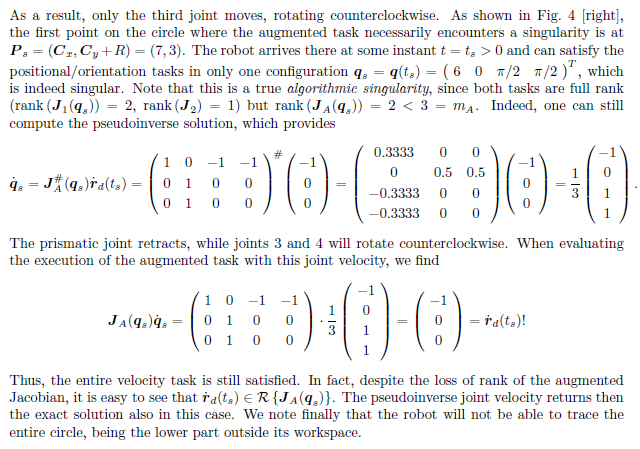

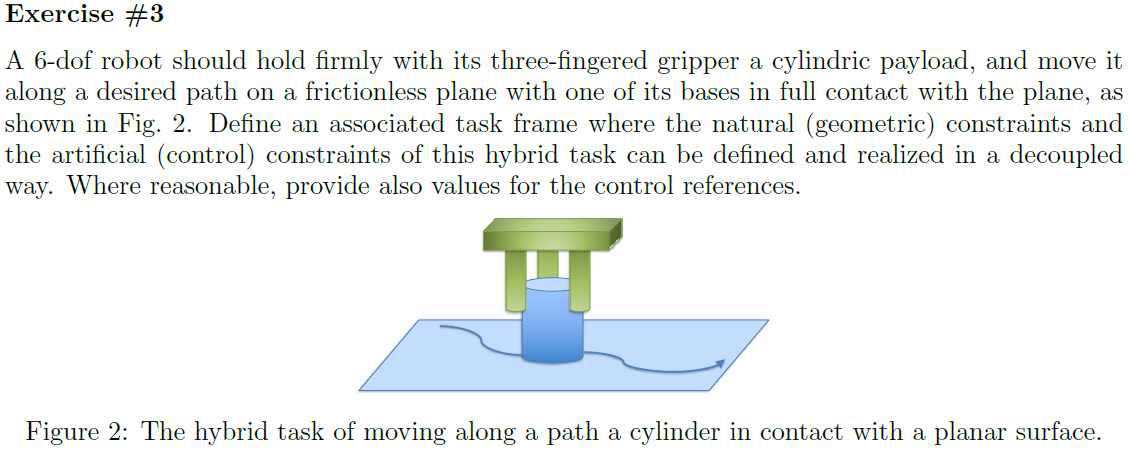

## natural cosntrains

## see one noe

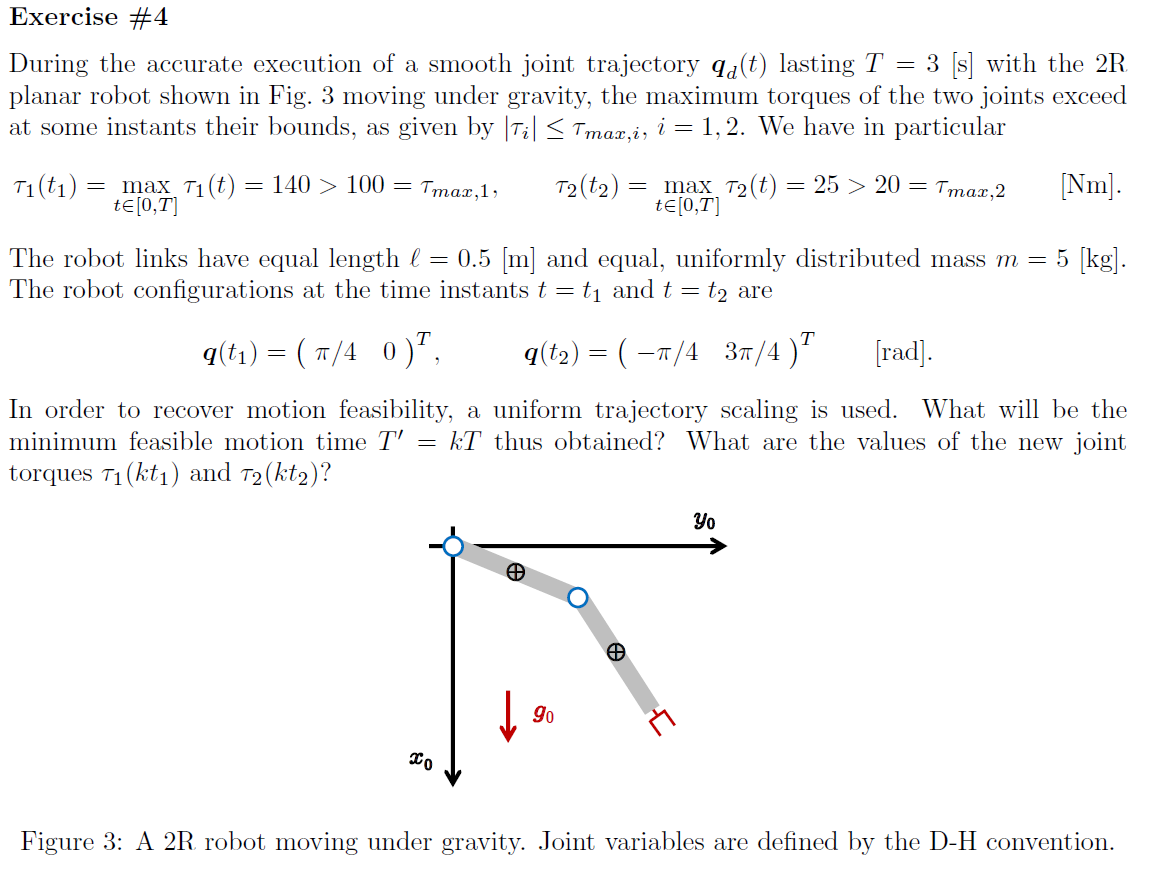

% % This part is isolated from previous section
% clear;clc;
% 
% % syms k q1(t) q2(t) q3(t)
% sigma = [0,0];
% n = length(sigma);
% % t = sym('t', 'real');
% q = sym('q_', [n 1],'real');
% qd = sym('q_dot_', [n 1],'real');
% qdd = sym('q_ddot_', [n 1],'real');
% %
% dc = sym('dc_', [n 1],'real');
% % k = sym('k', [n 1],'real');
% l = sym('l_', [n 1],'real');
% m = sym('m_', [n 1],'real');
% I = sym('I_', [n 1],'real');
% alpha_angle=sym('alpha','real')
% g0 = sym('g0','real');
% g=[g0,0,0]';

defining z struct

% R2Robot=['rr';'xx';sigma]
% z = Gen_param(n);
% z.sigmaD=R2Robot;
% z.l=l;
% z.q=q;
% z.q_dot=qd;
% z.dc=dc;
% z.m=m;
% z.I=I;
% z.methodD=1;
% % z.dhTable=[]
% z.firstParam='alpha';
% % z.rc=[];
% % z.movingframes=[];
% z.angle_=sym(zeros(1,n));
% l_0=sym('l','real')
% m_0=sym('m','real')
% z.opt_expr={[l;dc],[l_0,l_0,l_0/2,l_0/2]'};%not necessary
% l_=[l_0,l_0]';
% m_=[m_0,m_0]';
% % z.rcdefined=true;

## axis offset

% 
% % h=sym('h','real')
% % %x,y,z
% % z.xyx_offset=sym(zeros(3,n));
% % z.xyx_offset(:,1)=[0,0*h,0]'%

% %Global q reference?
% % clear
% % z.q_global
% z.global_q_reference=false;
% if(z.global_q_reference)
%     [z.q_global,z.q_dot_global]=convert_local2global_q(z.q,z.q_dot,z.sigmaD);
% end

% 
% %
% %
% % xyonly=true
% % [f,J,V,J_ps,PCVar,PC_EEShort,VarShortRobot]= getGenericPC_EE2(R2Robot,l,q,qd,dc,m,I,xyonly)
% % VarShortRobot.M
% % angle_desired=[0,0]
% % l(1)=0
% [Pc,vc,w,T,Ti,M,VarShortRobot,Trans] = getGenericPC2(z);

% M
% Pc
% simplify((Ti'))
% vc
% simplify(Trans.PTotal)
% Trans.PPartial{:}

% isMotor=false
% [g_q, PE, U,g_q_short,PE_short] = getGravityWithPc(Pc, q, l_, m_, dc, g, isMotor);

% g_q
% U{:}
% 

## evaluating gravity torques

## t1

% q1_=[pi/4,0]'
% l_def=sym('l','real')
% m_def=sym('m','real')
% l_=0.5
% m_=5
% g0_=9.81
% 
% vars2replace=[l_def;m_def;g0;q]
% vars2replace_=[l_;m_;g0_;q1_]
% g_q_t1_=vpa(subs(g_q,vars2replace,vars2replace_))

## t2

% q2_=[-pi/4,3*pi/4]'
% vars2replace=[l_def;m_def;g0;q]
% vars2replace_=[l_;m_;g0_;q2_]
% g_q_t2_=vpa(subs(g_q,vars2replace,vars2replace_))

## evaluating

% g1_torque_=g_q_t1_(1)
% g2_torque_=g_q_t2_(2)
% tau_max_1=100;
% tau_max_2=20;
% tau_q1_t1=140;
% tau_q2_t2=25;
% k1=sqrt((tau_q1_t1-g1_torque_)/(tau_max_1-g1_torque_))
% k2=sqrt((tau_q2_t2-g2_torque_)/(tau_max_2-g2_torque_))%% this is the maximun k we have to use this

## recomputing new maximun torques

% tau_q1_tk=(tau_q1_t1-g1_torque_)/k2^2+g1_torque_
% tau_q2_tk=(tau_q2_t2-g2_torque_)/k2^2+g2_torque_

## Exercise 5

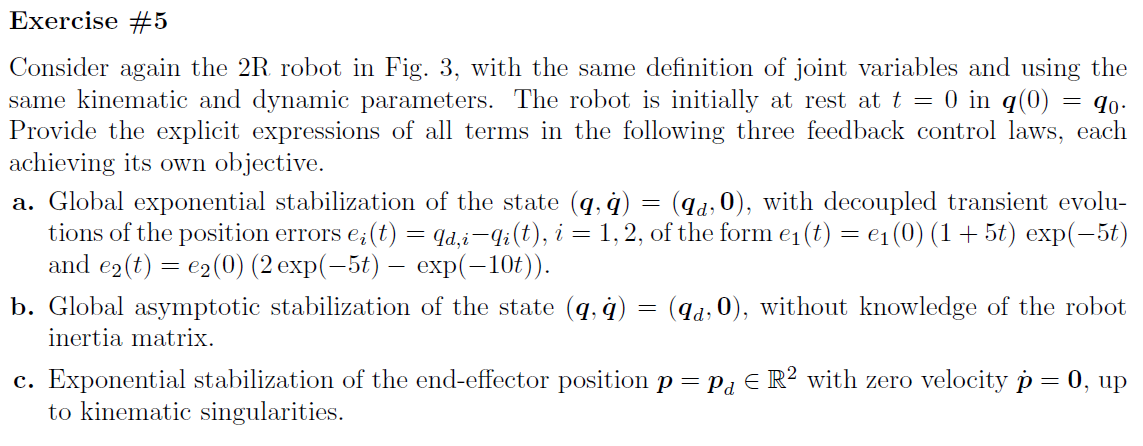

% % This part is isolated from previous section
% clear;clc
% 
% % syms k q1(t) q2(t) q3(t)
% sigma = [0,0];
% n = length(sigma);
% % t = sym('t', 'real');
% q = sym('q_', [n 1],'real');
% qd = sym('q_dot_', [n 1],'real');
% qdd = sym('q_ddot_', [n 1],'real');
% %
% dc = sym('dc_', [n 1],'real');
% % k = sym('k', [n 1],'real');
% l = sym('l_', [n 1],'real');
% m = sym('m_', [n 1],'real');
% I = sym('I_', [n 1],'real');
% alpha_angle=sym('alpha','real')
% g0 = sym('g0','real');
% g=[g0,0,0]';

defining z struct

% R2Robot=['rr';'xx';sigma]
% z = Gen_param(n);
% z.sigmaD=R2Robot;
% z.l=l;
% z.q=q;
% z.q_dot=qd;
% z.dc=dc;
% z.m=m;
% z.I=I;
% z.methodD=1;
% % z.dhTable=[]
% z.firstParam='alpha';
% % z.rc=[];
% % z.movingframes=[];
% z.angle_=sym(zeros(1,n));
% l_0=sym('l','real')
% m_0=sym('m','real')
% z.opt_expr={[l;dc],[l_0,l_0,l_0/2,l_0/2]'};%not necessary
% l_=[l_0,l_0]';
% m_=[m_0,m_0]';
% % z.rcdefined=true;

## axis offset

% 
% % h=sym('h','real')
% % %x,y,z
% % z.xyx_offset=sym(zeros(3,n));
% % z.xyx_offset(:,1)=[0,0*h,0]'%

% % %Global q reference?
% % % clear
% % % z.q_global
% % z.global_q_reference=false
% % if(z.global_q_reference)
% %     [z.q_global,z.q_dot_global]=convert_local2global_q(z.q,z.q_dot,z.sigmaD)
% % end

% 
% %
% %
% % xyonly=true
% % [f,J,V,J_ps,PCVar,PC_EEShort,VarShortRobot]= getGenericPC_EE2(R2Robot,l,q,qd,dc,m,I,xyonly)
% % VarShortRobot.M
% % angle_desired=[0,0]
% % l(1)=0
% [Pc,vc,w,T,Ti,M,VarShortRobot,Trans] = getGenericPC2(z);

% M
% Pc
% simplify((Ti'))
% vc
% simplify(Trans.PTotal)
% Trans.PPartial{:}

% isMotor=false
% [g_q, PE, U,g_q_short,PE_short] = getGravityWithPc(Pc, q, l_, m_, dc, g, isMotor)

% g_q
% U{:}

## control

## a)

% 
% t=sym('t','real');
% s=sym('s','real');
% e_1_0=sym('e_1_0','real');
% e_2_0=sym('e_2_0','real');
% e_=[e_1_0*(1+5*t)*exp(-5*t);e_2_0*2*exp(-5*t)-exp(-10*t)]
% z_global_exponential = feedback_linearization_control_global_exponential(z,e_)

## identifitying poles

% a_law_=z_global_exponential.law_
% a_law_laplace=z_global_exponential.law_laplace_
% 
% poles(a_law_laplace(1),s)
% poles(a_law_laplace(2),s)

## another way... did't work haha

% % K_D=z_global_exponential.mK_D;
% % K_P=z_global_exponential.mK_P;
% % a_law_factors_1=factor(a_law_(1))
% % kp_1_sol=solve(a_law_factors_1(2)==0,[K_P(1);K_D(1)])
% % simplify(subs(a_law_factors_1(2),kp_1_sol))

## b)